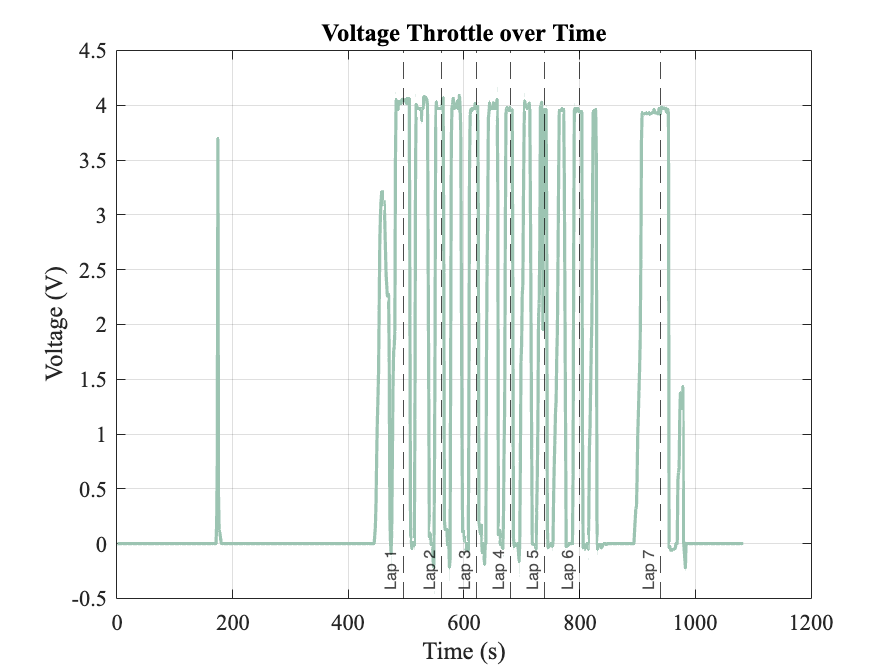

clear all
clc

% Read and preprocess data
Data = readtable('4Test10.05.xlsx');

% Throttle Data
Data1 = Data(~any(isnan(Data{:, {'Unix1', 'Lap1', 'Voltage'}}), 2), :);
TimeThrottle = Data1.Unix1 / 10^6;
LapThrottle = Data1.Lap1;
VoltageThrottle = Data1.Voltage;

% SOC Data
Data2 = Data(~any(isnan(Data{:, {'Unix2', 'Lap2', 'SOC', 'CAP_Volt'}}), 2), :);
TimeSOC = Data2.Unix2 / 10^6;
LapSOC = Data2.Lap2;
SOC = Data2.SOC;
CAP_Volt = Data2.CAP_Volt;

% IMU Z Axis Data
Data3 = Data(~any(isnan(Data{:, {'Unix3', 'Lap3', 'zAcc'}}), 2), :);
TimezAcc = Data3.Unix3 / 10^6;
LapzAcc = Data3.Lap3;
zAcc = Data3.zAcc;

% IMU X & Y Axis Data
Data4 = Data(~any(isnan(Data{:, {'Unix4', 'Lap4', 'xAcc', 'yAcc'}}), 2), :);
TimexAcc = Data4.Unix4 / 10^6;
LapxAcc = Data4.Lap4;
xAcc = Data4.xAcc;
TimeyAcc = Data4.Unix4 / 10^6;
LapyAcc = Data4.Lap4;
yAcc = Data4.yAcc;

% Velocity Data
Data5 = Data(~any(isnan(Data{:, {'Unix5', 'Lap5', 'Velocity'}}), 2), :);
TimeVelocity = Data5.Unix5 / 10^6;
LapVelocity = Data5.Lap5;
Velocity = Data5.Velocity / 10^3;

% GPS Data
Data6 = Data(~any(isnan(Data{:, {'Unix6', 'Lap6', 'Lat', 'Lon'}}), 2), :);
TimeGPS = Data6.Unix6 / 10^6;
LapGPS = Data6.Lap6;
Lat = Data6.Lat / 10^7;
Lon = Data6.Lon / 10^7;

% Current Data
Data7 = Data(~any(isnan(Data{:, {'Unix7', 'Lap7', 'Curr3'}}), 2), :);
TimeCurr3 = Data7.Unix7 / 10^6;
LapCurr3 = Data7.Lap7;
Curr3 = Data7.Curr3;

Data8 = Data(~any(isnan(Data{:, {'Unix8', 'Lap8', 'Curr2'}}), 2), :);
TimeCurr2 = Data8.Unix8 / 10^6;
LapCurr2 = Data8.Lap8;
Curr2 = Data8.Curr2;

Data9 = Data(~any(isnan(Data{:, {'Unix9', 'Lap9', 'Curr1'}}), 2), :);
TimeCurr1 = Data9.Unix9 / 10^6;
LapCurr1 = Data9.Lap9;
Curr1 = Data9.Curr1;

% Create a common time vector
commonTime = linspace(min([TimeThrottle; TimeSOC; TimezAcc; TimexAcc; TimeyAcc; TimeVelocity; TimeGPS; TimeCurr3; TimeCurr2; TimeCurr1]), ...
                      max([TimeThrottle; TimeSOC; TimezAcc; TimexAcc; TimeyAcc; TimeVelocity; TimeGPS; TimeCurr3; TimeCurr2; TimeCurr1]), 1000);

% Interpolate each dataset to the common time vector
VoltageThrottle_interp = interp1(TimeThrottle, VoltageThrottle, commonTime);
SOC_interp = interp1(TimeSOC, SOC, commonTime);
CAP_Volt_interp = interp1(TimeSOC, CAP_Volt, commonTime);
zAcc_interp = interp1(TimezAcc, zAcc, commonTime);
xAcc_interp = interp1(TimexAcc, xAcc, commonTime);
yAcc_interp = interp1(TimeyAcc, yAcc, commonTime);
Velocity_interp = interp1(TimeVelocity, Velocity, commonTime);
Lat_interp = interp1(TimeGPS, Lat, commonTime);
Lon_interp = interp1(TimeGPS, Lon, commonTime);
Curr3_interp = interp1(TimeCurr3, Curr3, commonTime);
Curr2_interp = interp1(TimeCurr2, Curr2, commonTime);
Curr1_interp = interp1(TimeCurr1, Curr1, commonTime);

% Initialize lap numbers from GPS data
laps = unique(LapGPS);

% Create a table to store the interpolated data
interpolatedData = table(commonTime', VoltageThrottle_interp', SOC_interp', CAP_Volt_interp', ...
    zAcc_interp', xAcc_interp', yAcc_interp', Velocity_interp', Lat_interp', Lon_interp', ...
    Curr3_interp', Curr2_interp', Curr1_interp', ...
    'VariableNames', {'Time', 'VoltageThrottle', 'SOC', 'CAP_Volt', 'zAcc', 'xAcc', 'yAcc', 'Velocity', 'Lat', 'Lon', 'Curr3', 'Curr2', 'Curr1'});

% Add Lap number to the interpolated data
interpolatedData.Lap = zeros(height(interpolatedData), 1);
for i = 1:length(laps)
    lapNum = laps(i);
    lapIndices = find(LapGPS == lapNum);
    if ~isempty(lapIndices)
        timeRange = TimeGPS(lapIndices);
        commonTimeIndices = find(commonTime >= min(timeRange) & commonTime <= max(timeRange));
        interpolatedData.Lap(commonTimeIndices) = lapNum;
    end
end

% Remove rows with NaN values
interpolatedData = rmmissing(interpolatedData);

% Constants
C = 29; % Supercapacitor capacitance in Farads
maxVoltage = 32.4; % Maximum supercapacitor voltage in Volts
constantPower = 10; % Constant power in Watts

% Calculate energy consumption
energyConsumption = zeros(size(interpolatedData.Time));
timeIntervals = [0; diff(interpolatedData.Time)]; % Time intervals in seconds

for i = 2:length(interpolatedData.Time)
    if interpolatedData.CAP_Volt(i) > maxVoltage - 0.1
        % E = Power * Time
        energyConsumption(i) = constantPower * timeIntervals(i);
    else
        % E = (V(i)^2 - V(i-1)^2) * C / 2
        energyConsumption(i) = abs((C * (interpolatedData.CAP_Volt(i)^2 - interpolatedData.CAP_Volt(i-1)^2)) / 2);
    end
end

% Add energy consumption to interpolated data
interpolatedData.EnergyConsumption = energyConsumption;

% Calculate cumulative energy consumption
cumulativeEnergy = cumsum(energyConsumption);

% Colors for each lap
colors = lines(length(laps));

% Plot properties
props = {'LineWidth', 2};
textProps = {'FontName', 'Times New Roman', 'FontSize', 14};

% Plotting Voltage Throttle
figure('Name', 'Voltage Throttle');
plot(commonTime, VoltageThrottle_interp, 'Color', "#9CC4B2", props{:});
addLapMarkers(LapThrottle, TimeThrottle, commonTime);
grid on;
title('Voltage Throttle over Time');
xlabel('Time (s)');
ylabel('Voltage (V)');
set(gca, textProps{:});


% Plotting SOC and Capacitor Voltage
figure('Name', 'SOC and Capacitor Voltage');
yyaxis left;
set(gca, 'YColor', 'k');  % Set right y-axis color to black
plot(commonTime, SOC_interp, 'Color', "#9CC4B2", 'LineWidth', 2, 'DisplayName', 'State of Charge (%)');
ylabel('State of Charge (%)');
yyaxis right;
set(gca, 'YColor', 'k');  % Set right y-axis color to black
plot(commonTime, CAP_Volt_interp, 'Color', "#E76D83", 'LineWidth', 2, 'DisplayName', 'Capacitor Voltage (V)');
ylabel('Capacitor Voltage (V)');
grid on;
title('SOC and Capacitor Voltage over Time');
xlabel('Time (s)');
set(gca, 'FontName', 'Times New Roman', 'FontSize', 14);
addLapMarkers(LapSOC, TimeSOC, commonTime);
legend('show');

% Plotting IMU X, Y, and Z Axes
figure('Name', 'IMU X, Y, and Z Axes');
subplot(3, 1, 1);
plot(commonTime, xAcc_interp, 'Color', "#9CC4B2", props{:});
addLapMarkers(LapxAcc, TimexAcc, commonTime);
grid on;
title('IMU X Axis over Time');
xlabel('Time (s)');
ylabel('xAcc (m/s^2)');
set(gca, textProps{:}, 'XColor', 'k', 'YColor', 'k');

subplot(3, 1, 2);
plot(commonTime, yAcc_interp, 'Color', "#E76D83", props{:});
addLapMarkers(LapyAcc, TimeyAcc, commonTime);
grid on;
title('IMU Y Axis over Time');
xlabel('Time (s)');
ylabel('yAcc (m/s^2)');
set(gca, textProps{:}, 'XColor', 'k', 'YColor', 'k');

subplot(3, 1, 3);
plot(commonTime, zAcc_interp, 'Color', "#672A4E", props{:});
addLapMarkers(LapzAcc, TimezAcc, commonTime);
grid on;
title('IMU Z Axis over Time');
xlabel('Time (s)');
ylabel('zAcc (m/s^2)');
set(gca, textProps{:}, 'XColor', 'k', 'YColor', 'k');

% Plotting Velocity
figure('Name', 'Velocity');
plot(commonTime, Velocity_interp, 'Color', "#9CC4B2", props{:});
addLapMarkers(LapVelocity, TimeVelocity, commonTime);
grid on;
title('Velocity over Time');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
set(gca, textProps{:});

% Plotting GPS Coordinates
figure('Name', 'GPS Coordinates');
gx = geoaxes;
hold(gx, 'on');
for i = 1:length(laps)
    lapData = (LapGPS == laps(i));
    geoscatter(gx, Lat(lapData), Lon(lapData), 'filled', 'MarkerEdgeColor', colors(i, :), 'MarkerFaceColor', colors(i, :));
end
geobasemap(gx, 'satellite');
title(gx, 'Geographical Path of Kitty Laps');
set(gx, 'FontSize', 14, 'FontName', 'Times New Roman');
legend(arrayfun(@(x) ['Lap ' num2str(x)], laps, 'UniformOutput', false), 'Location', 'northeast');
hold(gx, 'off');

% Plotting Currents
figure('Name', 'Currents');
subplot(3, 1, 1);
plot(commonTime, Curr3_interp, 'Color', "#9CC4B2", props{:});
addLapMarkers(LapCurr3, TimeCurr3, commonTime);
grid on;
title('Super Capacitor Current into DC/DC Motor over Time');
xlabel('Time (s)');
ylabel('Current (A)');
set(gca, textProps{:});

subplot(3, 1, 2);
plot(commonTime, Curr2_interp, 'Color', "#E76D83", props{:});
addLapMarkers(LapCurr2, TimeCurr2, commonTime);
grid on;
title('Motor Controller Current over Time');
xlabel('Time (s)');
ylabel('Current (A)');
set(gca, textProps{:});

subplot(3, 1, 3);
plot(commonTime, Curr1_interp, 'Color', "#672A4E", props{:});
addLapMarkers(LapCurr1, TimeCurr1, commonTime);
grid on;
title('Supercapacitor Charging Current over Time');
xlabel('Time (s)');
ylabel('Current (A)');
set(gca, textProps{:});

% Constants
C = 29; % Supercapacitor capacitance in Farads
maxVoltage = 32.4; % Maximum supercapacitor voltage in Volts
constantPower = 10; % Constant power in Watts

% Calculate energy consumption
energyConsumption = zeros(size(commonTime));
timeIntervals = [0 diff(commonTime)]; % Time intervals in seconds

for i = 2:length(commonTime)
    if VoltageThrottle_interp(i) > 0.5 && CAP_Volt_interp(i) < maxVoltage - 0.5
        % E = V^2 / 2C
        energyConsumption(i) = ((C*CAP_Volt_interp(i)^2) / (2)) * timeIntervals(i);
    elseif CAP_Volt_interp(i) == maxVoltage
        % E = Power * Time
        energyConsumption(i) = constantPower * timeIntervals(i);
    end
end

% Cumulative energy consumption
cumulativeEnergy = cumsum(energyConsumption);

% Plotting Velocity and Energy Consumption
figure('Name', 'Velocity and Energy Consumption');
yyaxis left;
plot(commonTime, Velocity_interp, 'Color', "#9CC4B2", props{:},'DisplayName', 'Velocity');
ylabel('Velocity (m/s)');
set(gca, 'YColor', 'k'); % Set y-axis color to black

yyaxis right;
plot(commonTime, cumulativeEnergy, 'Color', "#E76D83", props{:},'DisplayName', 'Energy Consumption');
ylabel('Cumulative Energy Consumption (Joules)');
set(gca, 'YColor', 'k'); % Set y-axis color to black

grid on;
title('Velocity and Cumulative Energy Consumption over Time');
xlabel('Time (s)');
set(gca, textProps{:});
addLapMarkers(LapVelocity, TimeVelocity, commonTime);
legend('show','Location','northwest');

% Plotting Energy Consumption and Throttle Voltage
figure('Name', 'Energy Consumption and Throttle Voltage');
yyaxis left;
plot(commonTime, VoltageThrottle_interp, 'Color', "#9CC4B2", 'LineWidth', 2, 'DisplayName', 'Throttle Voltage');
ylabel('Throttle Voltage (V)');
set(gca, 'YColor', 'k'); % Set y-axis color to black

yyaxis right;
plot(commonTime, cumulativeEnergy, 'Color', "#E76D83", 'LineWidth', 2, 'DisplayName', 'Energy Consumption ');
ylabel('Cumulative Energy Consumption (Joules)');
set(gca, 'YColor', 'k'); % Set y-axis color to black

grid on;
title('Energy Consumption and Throttle Voltage over Time');
xlabel('Time (s)');
set(gca, 'FontName', 'Times New Roman', 'FontSize', 14);
addLapMarkers(LapThrottle, TimeThrottle, commonTime);
legend('show','Location','northwest');

% Calculate lap metrics
lapMetrics = table('Size', [length(laps) 6], ...
                   'VariableTypes', {'double', 'double', 'double', 'double', 'double', 'double'}, ...
                   'VariableNames', {'Lap', 'DistanceCovered_km', 'LapTime_s', 'AverageVelocity_mps', 'EnergyConsumption_Wh', 'Rating_km_per_kWh'});

for i = 1:length(laps)
    lapNum = laps(i);
    lapIndices = find(interpolatedData.Lap == lapNum);

    if isempty(lapIndices)
        continue;  % Skip empty laps
    end

    lapMetrics.Lap(i) = lapNum;

    % Distance Covered (Haversine formula)
    lat = interpolatedData.Lat(lapIndices);
    lon = interpolatedData.Lon(lapIndices);
    R = 6371; % Earth's radius in km
    dlat = diff(lat) * pi / 180;
    dlon = diff(lon) * pi / 180;
    a = sin(dlat / 2).^2 + cos(lat(1:end-1) * pi / 180) .* cos(lat(2:end) * pi / 180) .* sin(dlon / 2).^2;
    c = 2 * atan2(sqrt(a), sqrt(1 - a));
    distance = R * sum(c); % Distance in km
    lapMetrics.DistanceCovered_km(i) = distance;

    % Lap Time
    lapTime = max(interpolatedData.Time(lapIndices)) - min(interpolatedData.Time(lapIndices));
    lapMetrics.LapTime_s(i) = lapTime;

    % Average Velocity
    avgVelocity = distance * 1000 / lapTime; % Average velocity in m/s
    lapMetrics.AverageVelocity_mps(i) = avgVelocity;

    % Energy Consumption
    energyConsumptionLap = sum(interpolatedData.EnergyConsumption(lapIndices)) / 3600; % Energy in Wh
    lapMetrics.EnergyConsumption_Wh(i) = energyConsumptionLap;

    % Rating (km/kWh)
    if energyConsumptionLap > 0
        rating = distance / (energyConsumptionLap / 1000); % km/kWh
    else
        rating = Inf;
    end
    lapMetrics.Rating_km_per_kWh(i) = rating;
end

% Sort laps by efficiency (most efficient to least efficient)
lapMetrics = sortrows(lapMetrics, 'Rating_km_per_kWh', 'descend');

% Display the lap metrics
disp(lapMetrics);

    Lap    DistanceCovered_km    LapTime_s    AverageVelocity_mps    EnergyConsumption_Wh    Rating_km_per_kWh
    ___    __________________    _________    ___________________    ____________________    _________________

     5          0.39234           58.559             6.6999                 1.1892                329.93      
     6           0.3952           138.81             2.8471                 1.4287                276.62      
     1          0.38789           65.065             5.9616                 1.7882                216.92      
     4          0.39059           57.475              6.796                 2.3813                164.03      
     7          0.20286           143.14             1.4172                 1.2556                161.57      
     3          0.

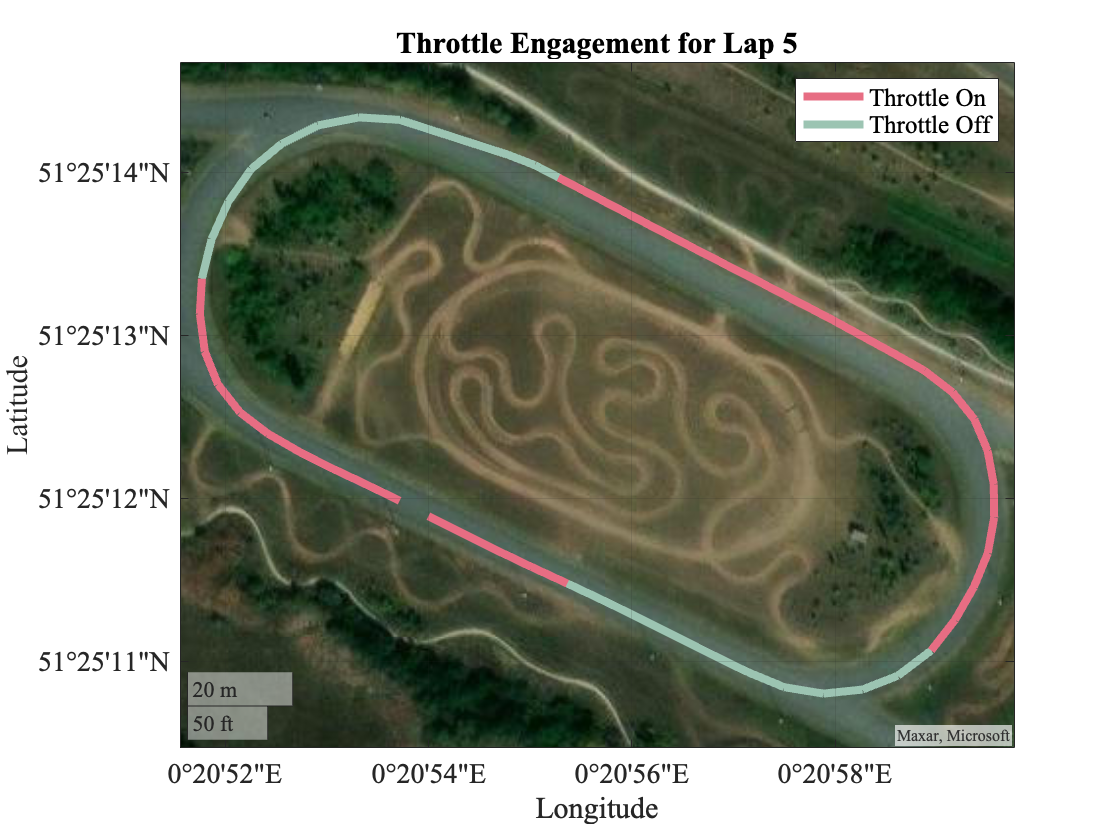


% Get user input for laps to compare
lap1 = input('Enter the first lap number to compare: ');
lap2 = input('Enter the second lap number to compare: ');

% Filter data for the selected laps
lap1Data = interpolatedData(interpolatedData.Lap == lap1, :);
lap2Data = interpolatedData(interpolatedData.Lap == lap2, :);

% Calculate cumulative distance for each lap starting from zero
cumDistLap1 = zeros(size(lap1Data, 1), 1);
cumDistLap2 = zeros(size(lap2Data, 1), 1);

for i = 2:length(lap1Data.Time)
    lat1 = deg2rad(lap1Data.Lat(i-1));
    lon1 = deg2rad(lap1Data.Lon(i-1));
    lat2 = deg2rad(lap1Data.Lat(i));
    lon2 = deg2rad(lap1Data.Lon(i));
    
    dlat = lat2 - lat1;
    dlon = lon2 - lon1;
    a = sin(dlat / 2)^2 + cos(lat1) * cos(lat2) * sin(dlon / 2)^2;
    c = 2 * atan2(sqrt(a), sqrt(1 - a));
    R = 6371000; % Earth's radius in meters
    distance = R * c;
    cumDistLap1(i) = cumDistLap1(i-1) + distance;
end

for i = 2:length(lap2Data.Time)
    lat1 = deg2rad(lap2Data.Lat(i-1));
    lon1 = deg2rad(lap2Data.Lon(i-1));
    lat2 = deg2rad(lap2Data.Lat(i));
    lon2 = deg2rad(lap2Data.Lon(i));
    
    dlat = lat2 - lat1;
    dlon = lon2 - lon1;
    a = sin(dlat / 2)^2 + cos(lat1) * cos(lat2) * sin(dlon / 2)^2;
    c = 2 * atan2(sqrt(a), sqrt(1 - a));
    R = 6371000; % Earth's radius in meters
    distance = R * c;
    cumDistLap2(i) = cumDistLap2(i-1) + distance;
end

% Calculate cumulative energy for each lap
cumEnergyLap1 = cumsum(lap1Data.EnergyConsumption);
cumEnergyLap2 = cumsum(lap2Data.EnergyConsumption);

% Plot Energy over Velocity for both laps
figure('Name', 'Lap Comparison with Velocity and Energy');

% Velocity profile on the left y-axis
yyaxis left;
plot(cumDistLap1, lap1Data.Velocity, '-', 'Color', "#672A4E", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d Velocity', lap1));
hold on;  % Hold on for multiple plots
plot(cumDistLap2, lap2Data.Velocity, '-', 'Color', "#E76D83", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d Velocity', lap2));
ylabel('Velocity (m/s)');
% Set the color of the left y-axis to black
set(gca, 'YColor', [0 0 0]);

% Energy profile on the right y-axis
yyaxis right;
plot(cumDistLap1, cumEnergyLap1, 'b--', 'Color', "#5B5941", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d Energy Consumption', lap1));
plot(cumDistLap2, cumEnergyLap2, 'r--', 'Color', "#9CC4B2", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d Energy Consumption', lap2));
ylabel('Cumulative Energy (Joules)');
% Set the color of the right y-axis to black
set(gca, 'YColor', [0 0 0]);
set(gca, 'FontSize', 14, 'FontName', 'Times New Roman');

% Set the color of the x-axis to black
set(gca, 'XColor', [0 0 0]);
set(gca, 'FontSize', 14, 'FontName', 'Times New Roman');

grid on;
xlabel('Distance from Start of Lap (m)');

% Title and Legend
title('Comparison of Velocity Profiles and Cumulative Energy for Two Laps');
set(gca, 'FontSize', 14, 'FontName', 'Times New Roman');
legend('show', 'Location', 'northwest');

% Geo-fence markers and labels (example values)
Corner1Entry = 83;  % Replace with actual values
Straight1Entry = 167;  % Replace with actual values
Corner2Entry = 286;  % Replace with actual values
Straight2Entry = 366;  % Replace with actual values

xline(Corner1Entry, '--', 'Corner 1 Entry', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
xline(Straight1Entry, '--', 'Straight 1 Entry', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
xline(Corner2Entry, '--', 'Corner 2 Entry', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
xline(Straight2Entry, '--', 'Straight 2 Entry', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');

hold off;  % Release hold for further plotting

% Create segments and plot for Lap 1
figure;
state = lap1Data.VoltageThrottle(1) > 0.2;

% Plot dummy lines for legend
hThrottleOnLap1 = geoplot(NaN, NaN, '-', 'Color', "#E76D83", 'LineWidth', 4, 'DisplayName', 'Throttle On');
hold on;
hThrottleOffLap1 = geoplot(NaN, NaN, '-', 'Color', "#9CC4B2", 'LineWidth', 4, 'DisplayName', 'Throttle Off');

for i = 1:height(lap1Data)-1
    if state
        geoplot(lap1Data.Lat(i:i+1), lap1Data.Lon(i:i+1), '-', 'Color', "#E76D83", 'LineWidth', 4);
    else
        geoplot(lap1Data.Lat(i:i+1), lap1Data.Lon(i:i+1), '-', 'Color', "#9CC4B2", 'LineWidth', 4);
    end
    state = lap1Data.VoltageThrottle(i+1) > 0.2;
end
title(sprintf('Throttle Engagement for Lap %d', lap1));
legend([hThrottleOnLap1, hThrottleOffLap1]); % Consolidated legend entries
geobasemap satellite; % Set satellite image as the background
set(gca, 'FontSize', 14, 'FontName', 'Times New Roman');
hold off;

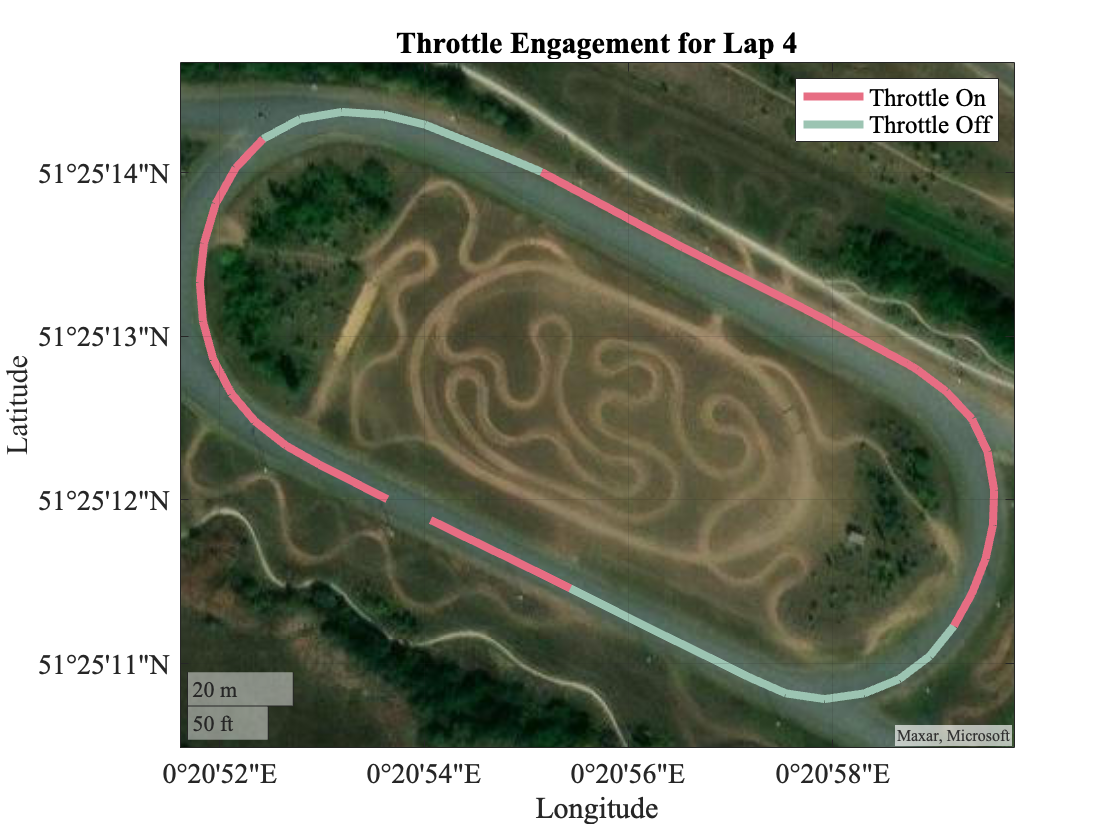


% Create segments and plot for Lap 2
figure;
state = lap2Data.VoltageThrottle(1) > 0.2;

% Plot dummy lines for legend
hThrottleOnLap2 = geoplot(NaN, NaN, '-', 'Color', "#E76D83", 'LineWidth', 4, 'DisplayName', 'Throttle On ');
hold on;
hThrottleOffLap2 = geoplot(NaN, NaN, '-', 'Color', "#9CC4B2", 'LineWidth', 4, 'DisplayName', 'Throttle Off ');

for i = 1:height(lap2Data)-1
    if state
        geoplot(lap2Data.Lat(i:i+1), lap2Data.Lon(i:i+1), '-', 'Color', "#E76D83", 'LineWidth', 4);
    else
        geoplot(lap2Data.Lat(i:i+1), lap2Data.Lon(i:i+1), '-', 'Color', "#9CC4B2", 'LineWidth', 4);
    end
    state = lap2Data.VoltageThrottle(i+1) > 0.2;
end
title(sprintf('Throttle Engagement for Lap %d', lap2));
legend([hThrottleOnLap2, hThrottleOffLap2]); % Consolidated legend entries
geobasemap satellite; % Set satellite image as the background
set(gca, 'FontSize', 14, 'FontName', 'Times New Roman');
hold off;

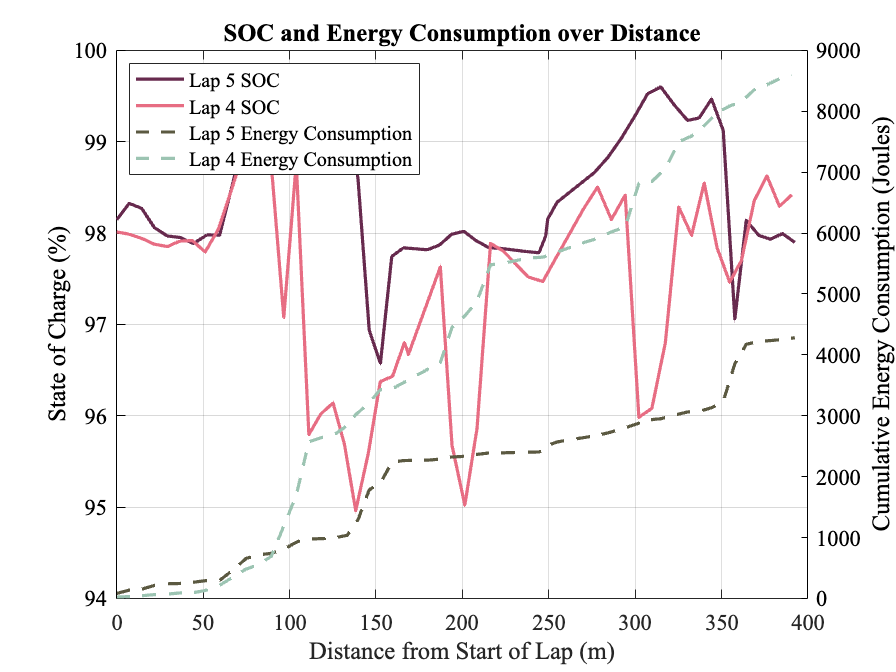


% 3-axis plot showing SOC and Energy Consumption for each lap over distance
figure('Name', 'SOC and Energy Consumption over Distance');

% Plot SOC for lap 1
yyaxis left;
plot(cumDistLap1, lap1Data.SOC, 'Color', "#672A4E", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d SOC', lap1));
ylabel('State of Charge (%)');
hold on;  % Hold on for multiple plots

% Plot SOC for lap 2
plot(cumDistLap2, lap2Data.SOC, 'LineStyle', '-', 'Color', "#E76D83", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d SOC', lap2));
set(gca, 'YColor', [0 0 0]);

% Plot Energy Consumption for lap 1
yyaxis right;
plot(cumDistLap1, cumEnergyLap1, 'b--', 'Color', "#5B5941", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d Energy Consumption', lap1));
ylabel('Cumulative Energy Consumption (Joules)');

% Plot Energy Consumption for lap 2
plot(cumDistLap2, cumEnergyLap2, 'r--', 'Color', "#9CC4B2", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d Energy Consumption', lap2));
set(gca, 'YColor', [0 0 0]);

grid on;
xlabel('Distance from Start of Lap (m)');
title('SOC and Energy Consumption over Distance');
set(gca, 'FontSize', 14, 'FontName', 'Times New Roman');
legend('show', 'Location', 'northwest');
hold off;

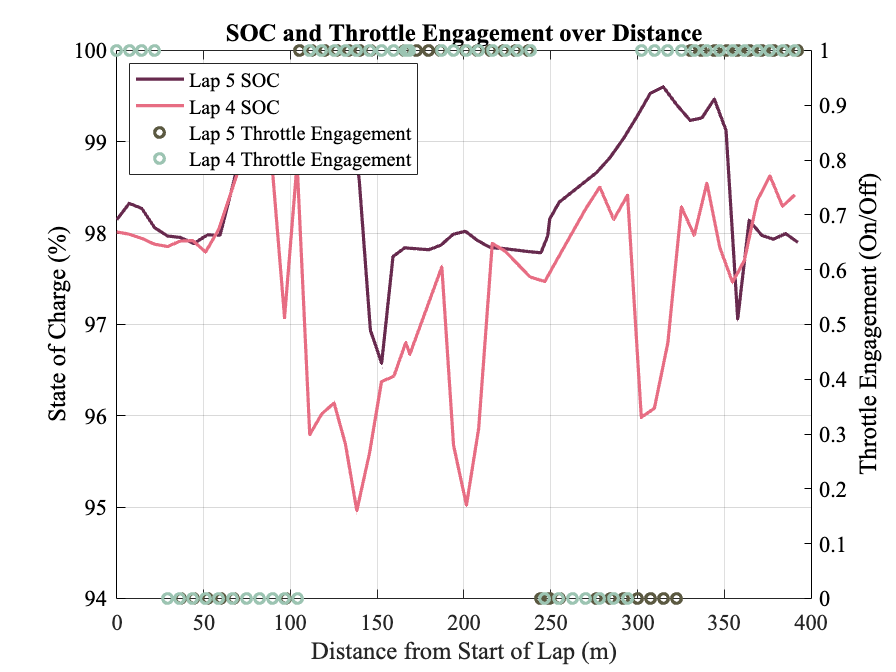

% 3-axis plot showing SOC and Throttle Engagement for each lap over distance
figure('Name', 'SOC and Throttle Engagement over Distance');

% Plot SOC for lap 1
yyaxis left;
plot(cumDistLap1, lap1Data.SOC, 'Color', "#672A4E", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d SOC', lap1));
ylabel('State of Charge (%)');
hold on;  % Hold on for multiple plots

% Plot SOC for lap 2
plot(cumDistLap2, lap2Data.SOC, "LineStyle", '-', 'Color', "#E76D83", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d SOC', lap2));
set(gca, 'YColor', [0 0 0]);

% Plot Throttle Engagement for lap 1
yyaxis right;
plot(cumDistLap1, lap1Data.VoltageThrottle > 0.2, 'o', 'Color', "#5B5941", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d Throttle Engagement', lap1));
ylabel('Throttle Engagement (On/Off)');

% Plot Throttle Engagement for lap 2
plot(cumDistLap2, lap2Data.VoltageThrottle > 0.2, 'o', 'Color', "#9CC4B2", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d Throttle Engagement', lap2));
set(gca, 'YColor', [0 0 0]);

grid on;
xlabel('Distance from Start of Lap (m)');
title('SOC and Throttle Engagement over Distance');
set(gca, 'FontSize', 14, 'FontName', 'Times New Roman');
legend('show', 'Location', 'northwest');
hold off;

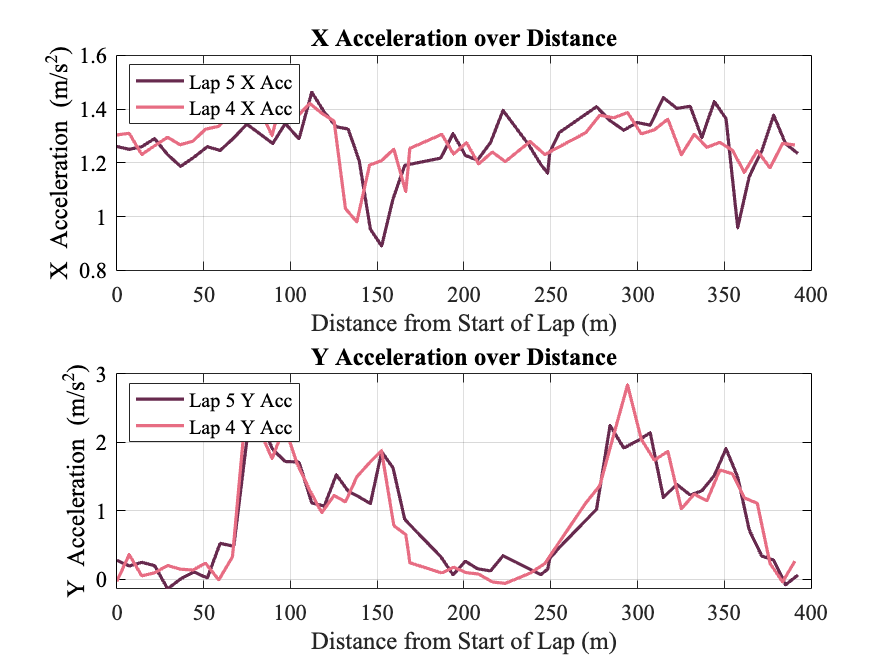


% 3-axis plot showing X and Y Acceleration for each lap over distance
figure('Name', 'X and Y Acceleration over Distance');

% Plot X Acceleration for lap 1
subplot(2, 1, 1);
plot(cumDistLap1, lap1Data.xAcc, 'Color', "#672A4E", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d X Acc', lap1));
ylabel('X Acceleration (m/s^2)');
hold on;  % Hold on for multiple plots

% Plot X Acceleration for lap 2
plot(cumDistLap2, lap2Data.xAcc, 'Color', "#E76D83", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d X Acc', lap2));
set(gca, 'YColor', [0 0 0]);

grid on;
xlabel('Distance from Start of Lap (m)');
title('X Acceleration over Distance');
set(gca, 'FontSize', 14, 'FontName', 'Times New Roman');
legend('show', 'Location', 'northwest');
hold off;

% Plot Y Acceleration for lap 1
subplot(2, 1, 2);
plot(cumDistLap1, lap1Data.yAcc, 'Color', "#672A4E", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d Y Acc', lap1));
ylabel('Y Acceleration (m/s^2)');
hold on;  % Hold on for multiple plots

% Plot Y Acceleration for lap 2
plot(cumDistLap2, lap2Data.yAcc, 'Color', "#E76D83", 'LineWidth', 2, 'DisplayName', sprintf('Lap %d Y Acc', lap2));
set(gca, 'YColor', [0 0 0]);

grid on;
xlabel('Distance from Start of Lap (m)');
title('Y Acceleration over Distance');
set(gca, 'FontSize', 14, 'FontName', 'Times New Roman');
legend('show', 'Location', 'northwest');
hold off;

function addLapMarkers(lapData, timeData, commonTime)
    lapChanges = find(diff(lapData) ~= 0) + 1;
    plottedLaps = [];  % Keep track of plotted laps
    for i = 1:length(lapChanges)
        currentLap = lapData(lapChanges(i));
        if currentLap ~= 0 && ~ismember(currentLap, plottedLaps)  % Only plot if lap not 0 and not already plotted
            [~, idx] = min(abs(timeData(lapChanges(i)) - commonTime));
            xline(commonTime(idx), '--k', ['Lap ' num2str(currentLap)], ...
                'HandleVisibility', 'off', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom');
            plottedLaps = [plottedLaps, currentLap];  % Mark this lap as plotted
        end
    end
end
